

% Time parameters
T = 10; % Total time (s), adjust if wheel speeds exceed 0.3 m/s
t = linspace(0, T, 1000);
u = 3.2 / T * t; % Linear parameterization
du_dt = 3.2 / T;

% Curve derivatives
dx_du = -1.0494 * sin(2.65 * (u + 1.4));
dy_du = -0.99 * cos(u + 1.4);
mag = sqrt(dx_du.^2 + dy_du.^2);

% Linear speed
v = mag * du_dt;

% Angular velocity via curvature
d2x_du2 = -2.7809 * cos(2.65 * (u + 1.4));
d2y_du2 = 0.99 * sin(u + 1.4);
% cross_mag = abs(dx_du .* d2y_du2 - dy_du .* d2x_du2);
cross_mag = dx_du .* d2y_du2 - dy_du .* d2x_du2;
kappa = cross_mag ./ (mag.^3);
omega = v .* kappa;

% Wheel velocities
d = 0.245; % Wheelbase (m)
v_R = v + (omega * d) / 2;
v_L = v - (omega * d) / 2;

% Check speed limit
max_speed = 0.3;
if max(max(abs(v_R)), max(abs(v_L))) > max_speed
    fprintf('Warning: Wheel speeds exceed %.2f m/s. Increase T to %.2f s.\n', ...
        max_speed, T * max(max(abs(v_R)), max(abs(v_L))) / max_speed);
end

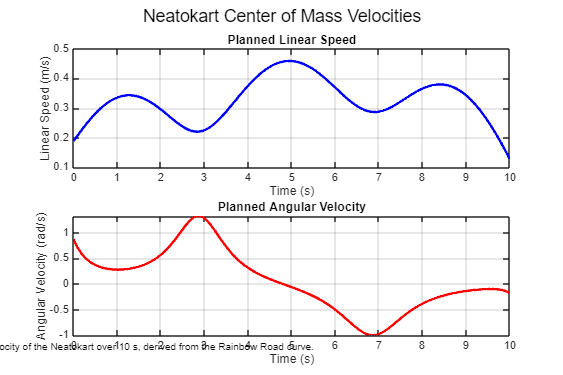


% Plot linear and angular velocities
figure('Position', [100, 100, 600, 400]);
subplot(2, 1, 1);
plot(t, v, 'b-', 'LineWidth', 2);
xlabel('Time (s)'); ylabel('Linear Speed (m/s)');
title('Planned Linear Speed');
grid on;
subplot(2, 1, 2);
plot(t, omega, 'r-', 'LineWidth', 2);
xlabel('Time (s)'); ylabel('Angular Velocity (rad/s)');
title('Planned Angular Velocity');
grid on;
sgtitle('Neatokart Center of Mass Velocities');
caption = sprintf('Planned linear speed and angular velocity of the Neatokart over %d s, derived from the Rainbow Road curve.', T);
text(0, -0.1, caption, 'FontSize', 8, 'HorizontalAlignment', 'center', 'Units', 'normalized');

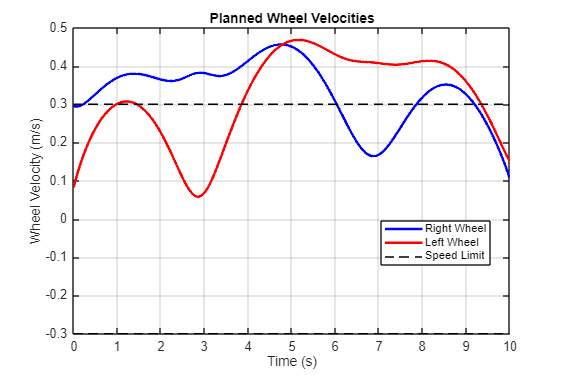


% Plot wheel velocities
figure('Position', [700, 100, 600, 400]);
plot(t, v_R, 'b-', 'LineWidth', 2, 'DisplayName', 'Right Wheel');
hold on;
plot(t, v_L, 'r-', 'LineWidth', 2, 'DisplayName', 'Left Wheel');
plot([0 T], [max_speed max_speed], 'k--', 'DisplayName', 'Speed Limit');
plot([0 T], [-max_speed -max_speed], 'k--', 'HandleVisibility', 'off');
xlabel('Time (s)'); ylabel('Wheel Velocity (m/s)');
title('Planned Wheel Velocities');
legend('Location', 'best');
grid on;
caption = sprintf('Left and right wheel velocities over %d s, constrained by ±0.3 m/s, for navigating Rainbow Road.', T);
text(T/2, -0.45, caption, 'FontSize', 8, 'HorizontalAlignment', 'center');
hold off;